%point = [0.233 1.424 2.656];
dbox = 101;
stbox = -0.1;
enbox = 0.1;
Xspace = linspace(stbox, enbox, dbox);% zahyou of order
Yspace = linspace(stbox, enbox, dbox);
Zspace = linspace(stbox, enbox, dbox);
dl = (enbox - stbox) / (dbox - 1);
rnum = 5;
valspace = zeros(length(Xspace), length(Yspace), length(Zspace));%kuggitta masume goto
xyzcheck = 0;

stepSize = 500;
indices = 1:stepSize:ptCloud.Count;
ptCloud = select(ptCloud,indices);
ptCloud;
%pcA = ptCloud.Location;

pcA = [0.04, 0.05, 0.07; -0.02, -0.06, -0.04];
pcX = vec2mat(pcA(:, 1), 1);
pcY = vec2mat(pcA(:, 2), 1);
pcZ = vec2mat(pcA(:, 3), 1);
cnt = 0;
pcX

pcX =     0.0400
   -0.0200


length(pcX)

ans = 2


for i = 1:length(pcX)
    i
    for x = 1:length(Xspace)% x = Order No of Xspace
        if (Xspace(1, x) <= pcX(i)) && (pcX(i) < Xspace(1, x + 1))
            for y = 1:length(Yspace)
                if (Yspace(1, y) <= pcY(i)) && (pcY(i) < Yspace(1, y + 1))
                    for z = 1:length(Zspace)
                        if (Zspace(1, z) <= pcZ(i)) && (pcZ(i) < Zspace(1, z + 1))
                            xyzcheck = 1;
                            break
                        end
                    end
                end
                if (xyzcheck == 1)
                    break
                end
            end
        end
        if (xyzcheck == 1)
            break
        end
    end
   
    for xx = (x - rnum): (x + rnum)
        if (1 > xx) || (xx > length(Xspace))
            continue;
        end
        
        for yy = (y - rnum): (y + rnum)
            if (1 > yy) || (yy > length(Yspace))
                continue;
            end
            
            for zz = (z - rnum): (z + rnum)
                if (1 > zz) || (zz > length(Zspace))
                    continue;
                end
                
                r = (Xspace(1, xx) - pcX(i)) ^ 2 + (Yspace(1, yy) - pcY(i)) ^ 2 + (Zspace(1, zz) - pcZ(i)) ^ 2;
                for m = 1:rnum
                    if r <= (m * dl) ^ 2
                        preval = valspace(xx, yy, zz);
                        valspace(xx, yy, zz) = valspace(xx, yy, zz) + (rnum - m) ^ 2;
                        if preval ~= valspace(xx, yy, zz)
                            Xspace(xx)
                            cnt = cnt + 1;
                        end
                        break;
                    end
                end
            end
        end
    end
    xyzcheck = 0;
end

i = 1

ans = 0.0320

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0360

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0380

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0400

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0420

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0440

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

ans = 0.0460

i = 2

ans = -0.0280

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0260

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0240

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0220

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0200

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0180

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0160

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

ans = -0.0140

cnt

cnt = 509

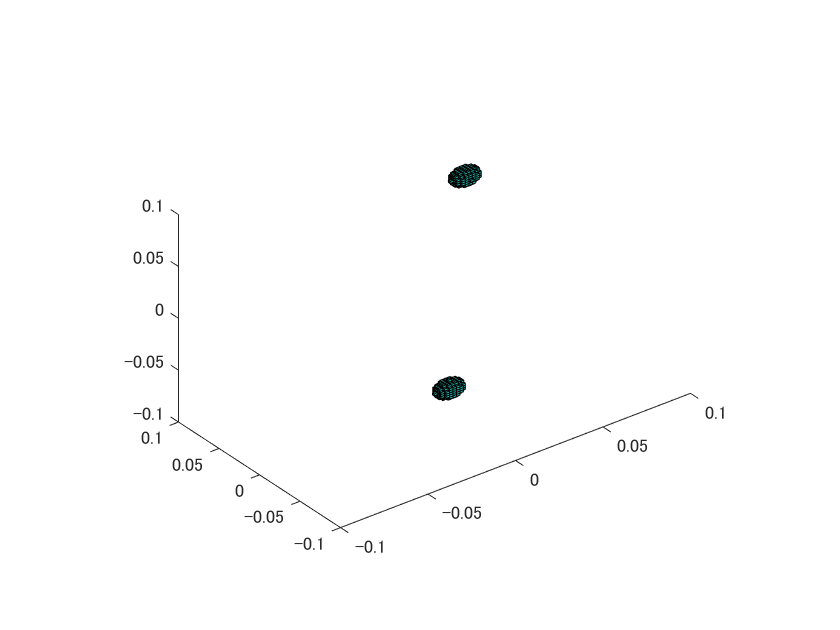


for x = 1:length(Xspace) - 1
    for y = 1:length(Yspace) - 1
        for z = 1:length(Zspace) - 1
            if valspace(x, y, z) > 0
            
            vert = [Xspace(1, x), Yspace(1, y), Zspace(1, z);
                    Xspace(1, x + 1), Yspace(1, y), Zspace(1, z);
                    Xspace(1, x + 1), Yspace(1, y + 1), Zspace(1, z);
                    Xspace(1, x), Yspace(1, y + 1), Zspace(1, z);
                    Xspace(1, x), Yspace(1, y), Zspace(1, z + 1);
                    Xspace(1, x + 1), Yspace(1, y), Zspace(1, z + 1);
                    Xspace(1, x + 1), Yspace(1, y + 1), Zspace(1, z + 1);
                    Xspace(1, x), Yspace(1, y + 1), Zspace(1, z + 1)] ;
            
            fac = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];
            
            C = [0; 0; 0; 0; 0; 0];
            p = patch('Vertices', vert, 'Faces', fac, 'FaceVertexCData', C, 'FaceColor', 'flat');
            hold on
            end
        end
    end
end

view(3) 
axis vis3d 

xlim([-0.1 0.1])
ylim([-0.1 0.1])
zlim([-0.1 0.1])